# LPF $\Gamma$ input to a uniform Transmission line

`The line is as follows`

- `L = 200 `$\mu$

- 
$$Z_L = 70 + j\omega 3\times10^9 \Omega$$


- 
$$R_g=50 \Omega$$


- `W = S = 20 `$\mu$

L = 200e-6;
W = 20e-6;
S = W;

Make a Coupled Microstrip Transmisison Line

coupledmicrostrip = coupledMicrostripLine(Length=200e-6, ...
                                            Width=20e-6, ...
                                            Spacing=20e-6, ...
                                            Height = 10e-6, ...
                                            GroundPlaneWidth=200e-6 ...
                                         )

coupledmicrostrip =   coupledMicrostripLine with properties:

              Length: 2.0000e-04
               Width: 2.0000e-05
             Spacing: 2.0000e-05
              Height: 1.0000e-05
    GroundPlaneWidth: 2.0000e-04
           Substrate: [1×1 dielectric]
           Conductor: [1×1 metal]


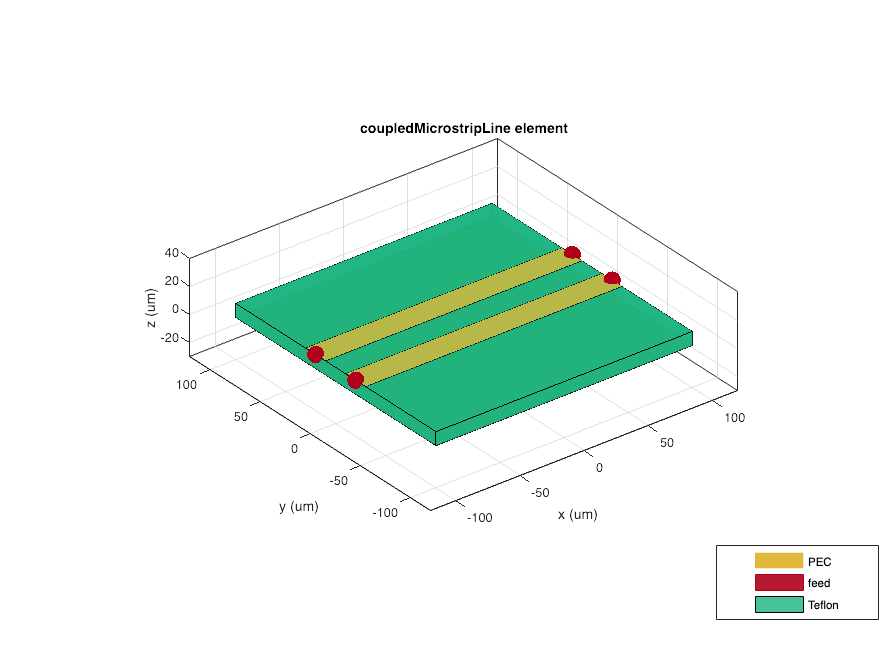

show(coupledmicrostrip)

Charactaristic Impedance

Z0 = getZ0(coupledmicrostrip)

Z0 = 64.7611 - 0.0200i

S parameters

s_params = sparameters(coupledmicrostrip, linspace(2e3, 1e11, 100),50)

s_params =   sparameters: S-parameters object

       NumPorts: 4
    Frequencies: [100×1 double]
     Parameters: [4×4×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


coefficient = gammain(s_params,Z0)

Error using CheckNetworkData
S_PARAMS must be a complex 2-by-2-by-M array.

Error in gammain (line 28)
nfreq = CheckNetworkData(s_params,2,'S_PARAMS');

Error in sparameters/gammain